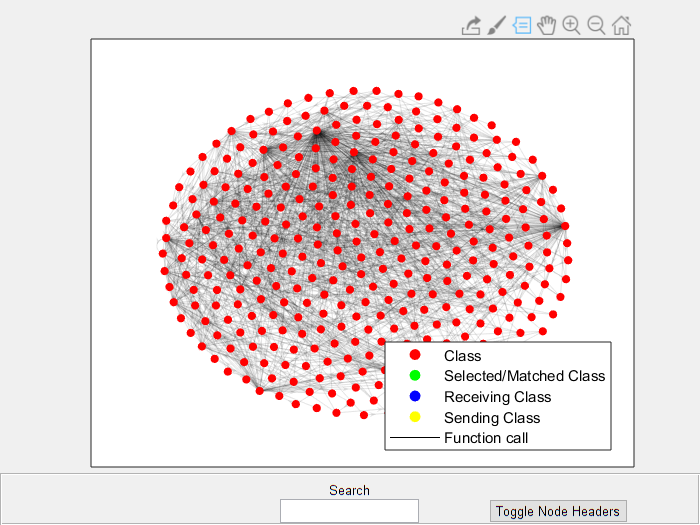

f = figure;

global G;
global h;
global nodeSize;
global nodeNeighbourSize;
global nodeSelectedSize;

nodeSize = 4;
nodeNeighbourSize = 6;
nodeSelectedSize = 8;

edges = importdata("get_edges_output.txt");
edges = split(edges);

start_nodes = edges(:,1);
end_nodes = edges(:,2);

G = digraph(start_nodes, end_nodes, 100000);

h = plot(G, "MarkerSize", nodeSize, "NodeColor", [1 0 0], "EdgeColor", [0 0 0]);
hold on

h.EdgeAlpha = 0.1;

layout(h,'force','WeightEffect', "direct", "UseGravity", true);

% k = findnode(G,"Repository");
% highlight(h,k,'NodeColor','g');

panel = uipanel(f, "Position", [0 0 1 0.1]);

toggleHeadersButton = uicontrol(panel, 'Style', 'togglebutton');
toggleHeadersButton.String = "Toggle Node Headers";
toggleHeadersButton.Units = "normalized";
toggleHeadersButton.Position = [0.7 0 0.2 0.5];
toggleHeadersButton.Callback = @toggleHeaders;

searchFieldLabel = uicontrol(panel, 'Style', 'text');
searchFieldLabel.String = "Search";
searchFieldLabel.Units = "normalized";
searchFieldLabel.Position = [0.4 0.35 0.2 0.5];

searchField = uicontrol(panel, 'Style', 'edit');
searchField.Units = "normalized";
searchField.Position = [0.4 0 0.2 0.5];
searchField.Callback = @searchByClassName;

hdt = datacursormode;
hdt.UpdateFcn = @(obj,event_obj) GraphCursorCallback(obj,event_obj,G.Nodes);

customLegend = zeros(5, 1);
customLegend(1) = plot(NaN, NaN, "or", "MarkerFaceColor", "r");
customLegend(2) = plot(NaN, NaN, "og", "MarkerFaceColor", "g");
customLegend(3) = plot(NaN, NaN, "ob", "MarkerFaceColor", "b");
customLegend(4) = plot(NaN, NaN, "oy", "MarkerFaceColor", "y");
customLegend(5) = plot(NaN, NaN, "-k");
legend(customLegend, "Class", "Selected/Matched Class", "Receiving Class", "Sending Class", "Function call", "Location", "best");


grid on

figure
adj = G.adjacency

adj =   (14,1)        1
  (15,1)        1
 (329,1)        1
   (1,2)        1
  (14,2)        1
  (16,2)        1
  (17,2)        1
  (19,2)        1
  (20,2)        1
  (22,2)        1
  (24,2)        1
  (26,2)        1
  (37,2)        1
  (39,2)        1
  (40,2)        1
  (41,2)        1
  (42,2)        1
  (43,2)        1
  (44,2)        1
  (45,2)        1
  (46,2)        1
  (47,2)        1
  (48,2)        1
  (55,2)        1
  (78,2)        1
 (297,2)        1
 (324,2)        1
 (334,2)        1
   (1,3)        1
   (5,3)        1
   (8,3)        1
  (10,3)        1
  (11,3)        1
  (12,3)        1
  (13,3)        1
  (15,3)        1
  (16,3)        1
  (17,3)        1
  (18,3)        1
  (19,3)        1
  (20,3)        1
  (21,3)        1
  (22,3)        1
  (23,3)        1
  (24,3)        1
  (25,3)        1
  (26,3)        1
  (27,3)        1
  (28,3)        1
  (29,3)        1
  (30,3)        1
  (31,3)        1
  (32,3)        1
  (33,3)        1
  (34,3)        1
  (3

adj = full(adj)

adj =      0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0 

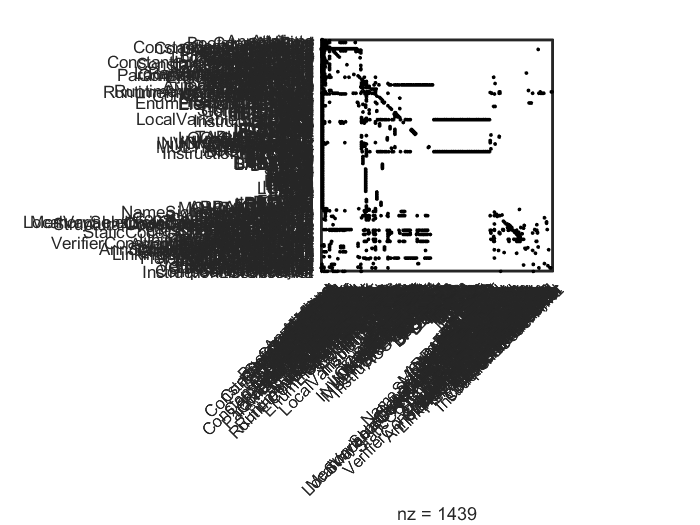

spy(adj, 7, "k")
xtickangle(45);
xticks(1:length(G.Nodes.Name))
xticklabels(G.Nodes.Name);

yticks(1:length(G.Nodes.Name))
yticklabels(G.Nodes.Name);


% view(3)

function toggleHeaders(src, event)
    global G;
    global h;

    if(src.Value == 1)
        h.NodeLabel = G.Nodes.Name;
    end
    
    if(src.Value == 0)
        h.NodeLabel = [];
    end
    
end

function searchByClassName(src, event)
    global G;
    global h;
    global nodeSize;
    global nodeSelectedSize;
    
    if(strtrim(src.String) ~= "")
        
        for i = 1 : size(G.Nodes, 1)

        formatString = strtrim(G.Nodes.Name(i));
        formatString = lower(formatString);
        
        formatInputString = strtrim(src.String);
        formatInputString = lower(formatInputString);

        TF = contains(formatString, formatInputString);
        match = findnode(G, G.Nodes.Name(i));

        if(TF)
            highlight(h, match,'NodeColor', [0 1 0], "MarkerSize", nodeSelectedSize);
            labelnode(h, match, G.Nodes.Name(i));
        else
            highlight(h,G.Nodes.Name(i),'NodeColor',[1 0 0], "MarkerSize", nodeSize);
            labelnode(h, match, "");
        end
     
        end  
    else
        h.NodeColor = [1 0 0];
        h.NodeLabel = [];
        h.MarkerSize = nodeSize;
    end
 
end